依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

热图A：naive aud-water, leant aud-water;

DataSet=TransferLearning.FullCalcium;

排序热图2

ALNaive=DataSet.QueryNTATS(UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'Fig2A'),UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median);

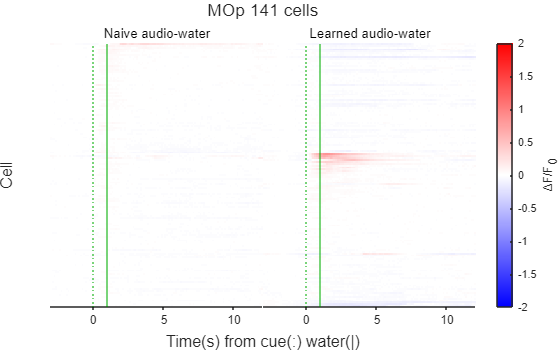

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
Data=ALNaive.NTATS{:,:,["Naive_audio_water","Learned_audio_water"]};
Layout=TransferLearning.AucGroupSortedHeatmap(Data,["Naive audio-water","Learned audio-water"],Colors,false);
title(Layout,sprintf('MOp %u cells',height(Data)));
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('Fig2A.svg'),'-dsvg');